# specDataOverview

A ideia deste arquivo de teste é apresentar a organização da principal propriedade do **appAnalise** – `specData` – acessível no app por `app.specData`.

Ela é uma instância da classe `model.SpecData`, que faz parte do projeto **appAnalise**, e tem como superclasse `model.SpecDataBase`, pertencente ao projeto **SupportPackages**.

A seguir, é mostrado um trecho da superclasse `model.SpecDataBase`.

Note que se trata de uma classe do tipo *handle*, o que significa que mudanças em suas propriedades são feitas **por referência** – ou seja, não são criadas cópias; qualquer modificação afeta diretamente o mesmo objeto na memória.

As principais informações armazenadas em `specData` são:

(a) **MetaData** – Estrutura com campos como `FreqStart`, `FreqStop`, `DataPoints`, `Resolution`, `TraceMode`, `Detector`, entre outros.

(b) **Data** – Lista com pelo menos três elementos:

- Data{1}: Vetor linha `1 x nSweeps` contendo os *timestamps*;

- Data{2}: Matriz `DataPoints x nSweeps` com os níveis das varreduras em dBm, dBμV ou dBµV/m;

- Data{3}: Matriz `DataPoints x 3` contendo informações de **MinHold**, **Average** e **MaxHold** de toda a monitoração.

Quando a monitoração é um *Drive-Test* conduzido pelo **appColeta**, do tipo *Level+Azimuth*, são adicionados dois elementos extras:

- Data{4}: Matriz `DataPoints x nSweeps` com os azimutes de cada ponto de medição em graus (de 0 a 360º);

- Data{5}: Matriz `DataPoints x nSweeps` com notas de qualidade dos azimutes (de 0 a 100%).

(c) **GPS** – Estrutura que resume a informação de localização da monitoração. Para *Drive-Tests*, esse campo contém apenas o ponto médio da rota.

(d) **RelatedFiles** – Tabela com informações detalhadas por arquivo, incluindo dados brutos de GPS, o que permite o georreferenciamento das varreduras, caso a coleta tenha sido realizada por meio de um *Drive-Test*.

A seguir, é mostrado um trecho da classe model.SpecData.

Note que uma instância de model.SpecData, além de herdar propriedades e métodos de model.SpecDataBase, tem as suas próprias propriedades e métodos. Dentre as propriedades, a mais importante é:

(e) **UserData** – Instância da classe model.User, que faz parte do projeto **appAnalise**, e armazena informações não originadas no arquivo bruto de medição, mas pelo appAnalise ou pelo próprio usuário.

## Aspectos gerais

No projeto SupportPackages, na pasta "tests/resources/SpecDataBase", tem alguns arquivos de referência gerados pelo Logger (RFEye), appColeta, CelPlan e Argus (R&S). No presente teste, será lido um arquivo desse pasta que foi gerado pelo Logger.

testFolder = fullfile(fileparts(fileparts(fileparts(fileparts(which('model.SpecDataBase'))))), 'tests');

% Cria instância da classe, inicialmente vazia.
specData   = model.SpecDataBase.empty;

## Leitura do arquivo

fileName   = fullfile(testFolder, 'resources', 'SpecDataBase', 'rfeye002292_210211_T111912.bin');
specData   = read(specData, fileName, 'SingleFile');

% O arquivo gerado pelo Logger possui informação espectral de quatro faixas
% de frequências.
specData

specData =   SpecDataBase with properties:

        Receiver: 'RFeye002292'
        MetaData: [1×1 struct]
            Data: {[1×82 datetime]  [5888×82 single]  [5888×3 single]}
             GPS: [1×1 struct]
    RelatedFiles: [1×10 table]
         FileMap: []
          Enable: on


% Faixas de frequências:
strjoin(arrayfun(@(x) sprintf('%.3f - %.3f MHz', x.MetaData.FreqStart/1e+6, x.MetaData.FreqStop/1e+6), specData, 'UniformOutput', false), '\n')

ans = '470.000 - 700.000 MHz'

## Informações registradas em um dos fluxos espectrais

idx = 2;
specData(idx)

ans =   SpecDataBase with properties:

        Receiver: 'RFeye002292'
        MetaData: [1×1 struct]
            Data: {[1×82 datetime]  [5888×82 single]  [5888×3 single]}
             GPS: [1×1 struct]
    RelatedFiles: [1×10 table]
         FileMap: []
          Enable: on


% Pelas dimensões de "Data", evidencia-se que foram coletadas 245 varreduras, e que 
% cada varredura é formada por 1024 pontos.

% Na propriedade "MetaData" são registrados os principais metadados - FreqStart, 
% FreqStop, Resolution e VBM, tudo em "Hertz", além do número de pontos por
% varredura (DataPoints), o modo de traço (TraceMode), o detector, dentre outros.
specData(idx).MetaData

ans = struct with fields:
            DataType: 67
           FreqStart: 470000000
            FreqStop: 700000000
          DataPoints: 5888
          Resolution: 73828
                 VBW: -1
           Threshold: -1
           TraceMode: 'Peak'
    TraceIntegration: -1
            Detector: ''
           LevelUnit: 'dBµV/m'
             Antenna: [1×1 struct]
              Others: ''


% Sumarização da informação do GPS...
specData(idx).GPS

ans = struct with fields:
            Status: 1
             Count: 1
          Latitude: -12.9716
         Longitude: -38.4815
      Latitude_std: 0
     Longitude_std: 0
          stdRange: [100 100 100]
          Location: 'Salvador/BA'
    LocationSource: 'API'
            Edited: 0


% Arquivos relacionados ao fluxo espectral... nem sempre a relação será de
% um para um já que o appAnalise mescla fluxos que possuem os mesmos
% metadados.
specData(idx).RelatedFiles

ans = 1×10 table
                   File                      Task       ID                 Description                       BeginTime                EndTime           nSweeps    RevisitTime        GPS                           uuid                  
    __________________________________    __________    __    ______________________________________    ____________________    ____________________    _______    ___________    ____________    ________________________________________

    {'rfeye002292_210211_T112524.bin'}    {'Script'}    40    {'PRD 2021 (Faixa principal 4 de 4).'}    11-Feb-2021 11:25:24    11-Feb-2021 11:26:45      82          1.001 

% A informação detalhada de GPS fica em coluna da tabela "RelatedFiles",
% no campo "Matrix".
specData(idx).RelatedFiles.GPS{1}

ans = struct with fields:
            Status: 1
             Count: 1
          Latitude: -12.9716
         Longitude: -38.4815
      Latitude_std: 0
     Longitude_std: 0
          stdRange: [100 100 100]
          Location: 'Salvador/BA'
    LocationSource: 'API'
            Matrix: [-12.9716 -38.4815]
            Edited: 0


% Latitude e Longitude, ambos organizados em coluna.
specData(idx).RelatedFiles.GPS{1}.Matrix

ans =   -12.9716  -38.4815


% Um trecho do vetor linha de timestamps...
specData(idx).Data{1}(1:10)

ans = 1×10 datetime array
   11/02/2021 11:25:24   11/02/2021 11:25:25   11/02/2021 11:25:26   11/02/2021 11:25:27   11/02/2021 11:25:28   11/02/2021 11:25:29   11/02/2021 11:25:30   11/02/2021 11:25:31   11/02/2021 11:25:32   11/02/2021 11:25:33


% E um trecho da matriz de níveis...
specData(idx).Data{2}(1:10,1:10)

ans = 10×10 single matrix
   31.5000   41.0000   41.0000   42.0000   40.5000   45.0000   41.0000   40.5000   36.5000   36.0000
   30.0000   42.5000   40.0000   41.5000   42.5000   41.5000   49.0000   41.0000   18.0000   34.0000
   38.0000   44.0000   40.5000   35.5000   43.5000   33.5000   49.5000   40.5000   31.0000   31.0000
   46.0000   39.0000   36.0000   45.5000   33.5000   45.5000   46.5000   43.0000   24.0000   41.0000
   47.5000   41.0000   35.0000   48.0000   46.5000   48.0000   43.5000   40.5000   42.5000   43.5000
   45.5000   45.5000   34.0000   49.0000   47.0000   40.5000   41.5000   38.0000   46.0000   41.0000
   32.0000   41.0000   34.0000   48.5000   46.5000   30.5000   39.5000   30.5000   40.5000   39.0000
   40.5000   46.0000   37.5000   47.5000   46.0000   44.0000   33.5000   34.5000   40.5000   40.0000
   42.0000   53.5000   46.5000   48.0000   48.5000   50.5000   36.0000   42.0000   45.5000   42.5000
   55.0000   55.5000   46.5000   54.0000   56.5000   58.5000   47

## Uma simples análise: busca pelo máximo e plot

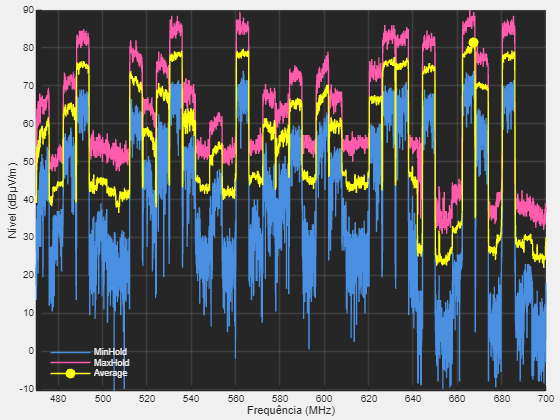

% Identificação do ponto de máximo na curva de média para 
% mostrar como um marcados no plot. Lembrando que o elemento
% Data{3} é uma matriz DataPoints x 3 contendo informações de 
% MinHold, Average e MaxHold de toda a monitoração.
[~, idxPeakMax] = max(specData(idx).Data{3}(:,2));

% Criação de figura e eixo:
f  = uifigure();
ax = uiaxes(f, 'Units', 'normalized', 'Position', [0.01,0.01,.98,.98], ...
               'YGrid', 'on', 'XGrid', 'on', 'GridColor', [.8,.8,.8],  ...
               'Color', [.15,.15,.15], 'FontSize', 10);

% Configuração do eixo:
xData = linspace(specData(idx).MetaData.FreqStart / 1e+6, ... % Hertz >> MHz
                 specData(idx).MetaData.FreqStop  / 1e+6, ...
                 specData(idx).MetaData.DataPoints);

[yDataMin, yDataMax] = bounds(specData(idx).Data{3}, "all");

set(ax, XLim = [xData(1), xData(end)], YLim = [yDataMin, yDataMax])
xlabel(ax, 'Frequência (MHz)')
ylabel(ax, ['Nível (' specData(idx).MetaData.LevelUnit ')'])
legend(ax, 'Location', 'southwest', 'Box', 'off', 'TextColor', [.94,.94,.94])
hold(ax, "on")

% Plot
plot(ax, xData, specData(idx).Data{3}(:,1), 'Color', '#4A90E2', 'DisplayName', 'MinHold');
plot(ax, xData, specData(idx).Data{3}(:,3), 'Color', '#FF5CAD', 'DisplayName', 'MaxHold');
plot(ax, xData, specData(idx).Data{3}(:,2), 'Color', '#ffff12', 'DisplayName', 'Average', 'MarkerIndices', idxPeakMax, 'Marker', 'o', 'MarkerSize', 7, 'MarkerFaceColor', '#ffff12');